% Define the time vector
t = linspace(0, 2*pi, 10000);

% Define two signals x(t) and y(t)
x = sin(t);          % Sine wave signal
y = cos(t);          % Cosine wave signal

% Compute the inner product (dot product in continuous domain)
inner_product = trapz(t, x .* y);

% Display the result
disp(['Inner Product: ', num2str(inner_product)]);

Inner Product: -1.1102e-16


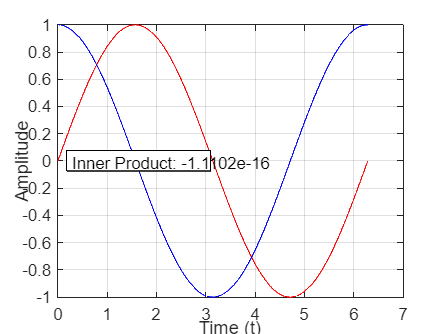


% Plot the signals
figure;
plot(t, x, 'r');
hold on; 
plot(t, y, 'b');
xlabel('Time (t)');
ylabel('Amplitude');
grid on;

% Annotation on the plot
annotation('textbox', [0.15, 0.45, 0.3, 0.1], 'String', ['Inner Product: ', num2str(inner_product)], 'FitBoxToText','on', 'BackgroundColor','white');


if abs(inner_product) < 1e-10
    disp('The signals are orthogonal.');
else
    disp('The signals are not orthogonal.');
end

The signals are orthogonal.
